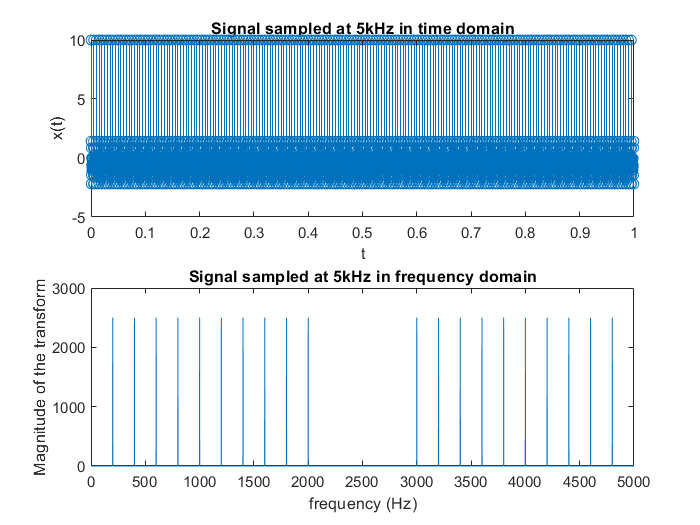

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
f_cheating = 50000; % "Cheating" frequency, simulate we are dealing with "analogue" signal whereas we are not.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

% for j = 1:10
%     figure;
%     plot(n*T, x(j,:))
% end
signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n*T, signal_supersition);
xlabel('t');
ylabel('x(t)');
title('Signal sampled at 5kHz in time domain');
soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');

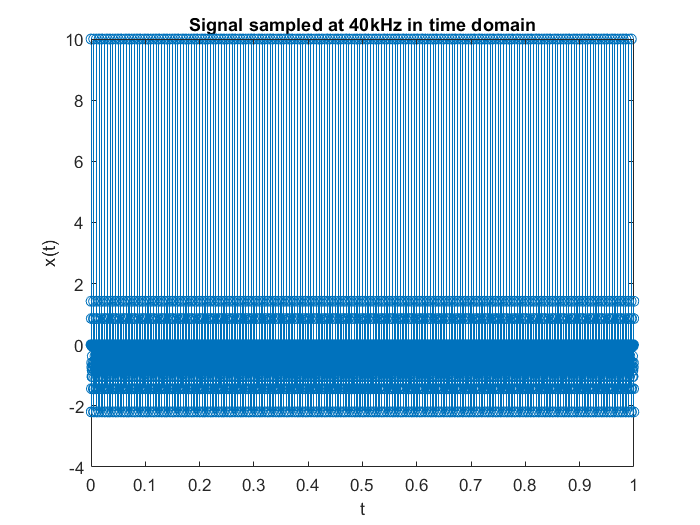

figure
% Since the required sampling frequency after doing up sampling is not a
% integral multiple of the original sampling frequency, we have to firt do
% the up sampling, then do the down sampling. Meaning, first do upsampling by
% 8 times, then down sample by 5 times.
signal_interleave_with_zeros = zeros(1, 40000);
index = 1;
for i = 1:40000
    if mod(i, 8) == 1
        signal_interleave_with_zeros(i) = signal_supersition(index);
        index = index + 1;
    end
end
k = 0:1/40000:39999/40000;
stem(k, signal_interleave_with_zeros)
xlabel('t');
ylabel('x(t)');
title('Signal sampled at 40kHz in time domain');

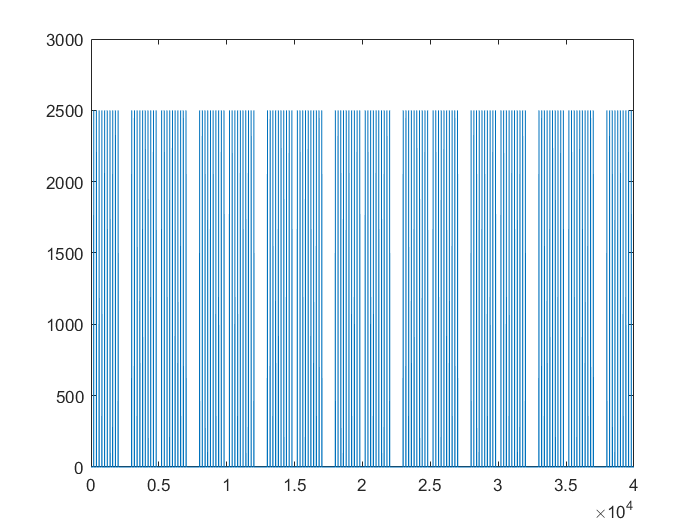

fft_for_upsampling = fft(signal_interleave_with_zeros);
f = 0:39999;
plot(f, abs(fft_for_upsampling));

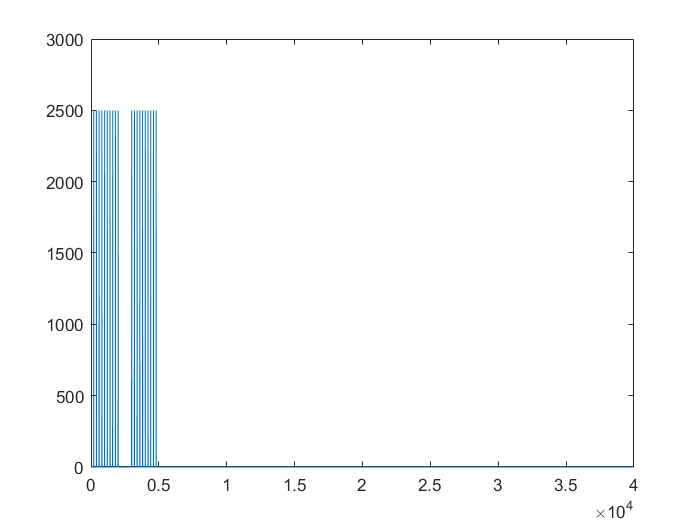


fft_after_filtering = [(fft_for_upsampling(1:2001)), zeros(1, 37999)];
fft_after_filtering = [(fft_for_upsampling(1:2001)), zeros(1, 35998), fft_for_upsampling(38000:40000)];
fft_after_filtering = [(fft_for_upsampling(1:5001)), zeros(1, 34999)];
k = 0:39999;
plot(k, abs(fft_after_filtering))

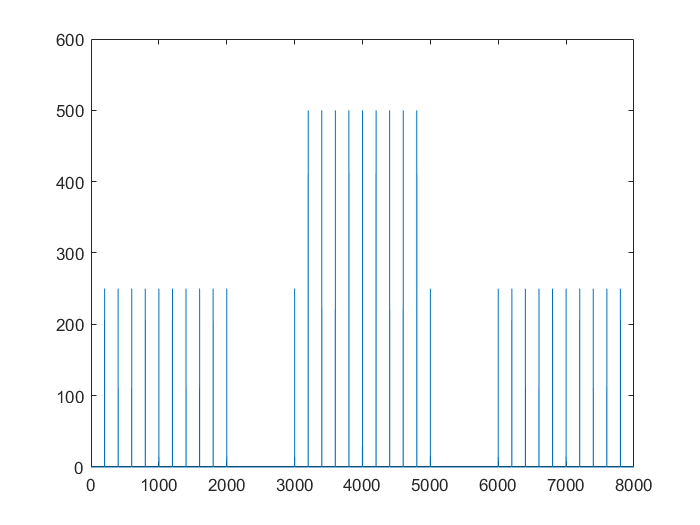

signal_after_filtering = real(ifft(fft_after_filtering));
signal_after_downsampling = zeros(1, 8000);
index = 1;
for i = 1:40000
    if mod(i, 5) == 1
        signal_after_downsampling(index) = signal_after_filtering(i);
        index = index + 1;
    end
end
fft_for_downsampling = fft(signal_after_downsampling);
k = 0:7999;
plot(k, abs(fft_for_downsampling))

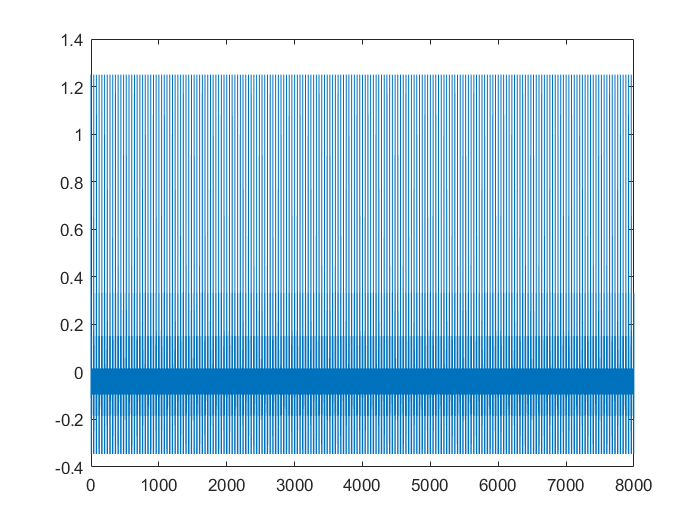

% soundsc(signal_after_downsampling)
plot(k, signal_after_downsampling)